%24/02/2024 A CUBIC B-SPLINE ALGORITHM WITH (NOT OPEN) UNIFORM KNOT VECTOR
%26/02/2024 changed 'ControlPoints' to 'CP', added scatter to graph,
%           changed path from loop
SumN = 0;
SumNPx = 0;
SumNPy = 0;
k1 = [];
k2 = [];
k3 = [];
NStack = [];
Stackx = [];
Stacky = [];
T = [];
%for k = 3
P1 = [0,50];
P2 = [20,50];
P3 = [40,100];
P4 = [60,0];
P5 = [100,50];
t1 = 0;
t2 = 10;
t3 = 20;
t4 = 30;
t5 = 40;
t6 = 50;
t7 = 60;
t8 = 70;
tvmin = t3;
tvmax = t6;
tmin = 0;
tmax = 80;
step = 0.1;
Knot = [t1,t2,t3,t4,t5,t6,t7,t8];
for t = tmin:step:tmax-step
    if (t1<=t)
        if (t<t2)
            N1k1 = 1;
        else
            N1k1 = 0;
        end
    else
        N1k1 = 0;
    end
    if (t2<=t)
        if (t<t3)
            N2k1 = 1;
        else
            N2k1 = 0;
        end
    else
        N2k1 = 0;
    end
    if (t3<=t)
        if (t<t4)
            N3k1 = 1;
        else
            N3k1= 0;
        end
    else
        N3k1 = 0;
    end
    if (t4<=t)
        if (t<t5)
            N4k1 = 1;
        else
            N4k1 = 0;
        end
    else
        N4k1 = 0;
    end
    if (t5<=t)
        if (t<t6)
            N5k1 = 1;
        else
            N5k1 = 0;
        end
    else
        N5k1 = 0;
    end
    if (t6<=t)
        if (t<t7)
            N6k1 = 1;
        else
            N6k1 = 0;
        end
    else
        N6k1 = 0;
    end
    if (t7<=t)
        if (t<t8)
            N7k1 = 1;
        else
            N7k1 = 0;
        end
    else
        N7k1 = 0;
    end
    N1k2 = ((t-t1)/(t2-t1))*N1k1 + ((t3-t)/(t3-t2))*N2k1;
    N2k2 = ((t-t2)/(t3-t2))*N2k1 + ((t4-t)/(t4-t3))*N3k1;
    N3k2 = ((t-t3)/(t4-t3))*N3k1 + ((t5-t)/(t5-t4))*N4k1;
    N4k2 = ((t-t4)/(t5-t4))*N4k1 + ((t6-t)/(t6-t5))*N5k1;
    N5k2 = ((t-t5)/(t6-t5))*N5k1 + ((t7-t)/(t7-t6))*N6k1;
    N6k2 = ((t-t6)/(t7-t6))*N6k1 + ((t8-t)/(t8-t7))*N7k1;

    N1k3 = ((t-t1)/(t3-t1))*N1k2 + ((t4-t)/(t4-t2))*N2k2;
    N2k3 = ((t-t2)/(t4-t2))*N2k2 + ((t5-t)/(t5-t3))*N3k2;
    N3k3 = ((t-t3)/(t5-t3))*N3k2 + ((t6-t)/(t6-t4))*N4k2;
    N4k3 = ((t-t4)/(t6-t4))*N4k2 + ((t7-t)/(t7-t5))*N5k2;
    N5k3 = ((t-t5)/(t7-t5))*N5k2 + ((t8-t)/(t8-t6))*N6k2;

    SumNPx = N1k3*P1(1,1) + N2k3*P2(1,1) + N3k3*P3(1,1) + N4k3*P4(1,1) + N5k3*P5(1,1);
    SumNPy = N1k3*P1(1,2) + N2k3*P2(1,2) + N3k3*P3(1,2) + N4k3*P4(1,2) + N5k3*P5(1,2);
    if t >= tvmin
        if t<=tvmax
            Stackx = [Stackx; SumNPx];
            Stacky = [Stacky; SumNPy];
        end
    end
    k1 = [k1; N1k1, N2k1, N3k1, N4k1, N5k1, N6k1, N7k1];
    k2 = [k2; N1k2, N2k2, N3k2, N4k2, N5k2, N6k2];
    k3 = [k3; N1k3, N2k3, N3k3, N4k3, N5k3];
end
k1;
k2;
k3;
%CleanX = nonzeros(Stackx);
%CleanY = nonzeros(Stacky);
%StackPlot = [Stackx, Stacky]
CP = [P1; P2; P3; P4; P5]

CP =      0    50
    20    50
    40   100
    60     0
   100    50


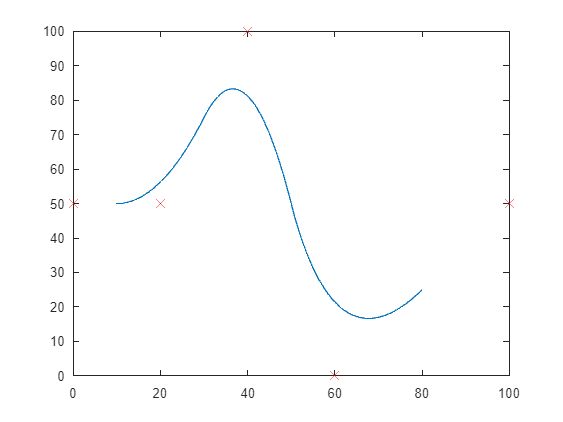

plot(Stackx, Stacky)
hold on
scatter(CP(:,1),CP(:,2), 100, 'X', 'red')

Knot

Knot =      0    10    20    30    40    50    60    70


%plot(CleanX,CleanY)

